# HW: Satellite NPP

% safety first
close all
clear all

% read in the data
fn='NPP_VGPM_MODISR18_3x3_2003_2018.nc';
%ncdisp(fn); % display data contents
lon=ncread(fn,'lon');
lat=ncread(fn,'lat');
time=ncread(fn,'time');
NPP=ncread(fn,'NPP');

(1) Contrast the northern and southern high latitude productivity. Perform zonal (longitudinal) mean at 50°N and 50°S and plot the time series together. [**¶**](http://localhost:8891/notebooks/4305-PCOcean/2021/week11_npp_exercise.ipynb#generate-time-average-(long-term-mean)-and-make-a-global-map-quickly)

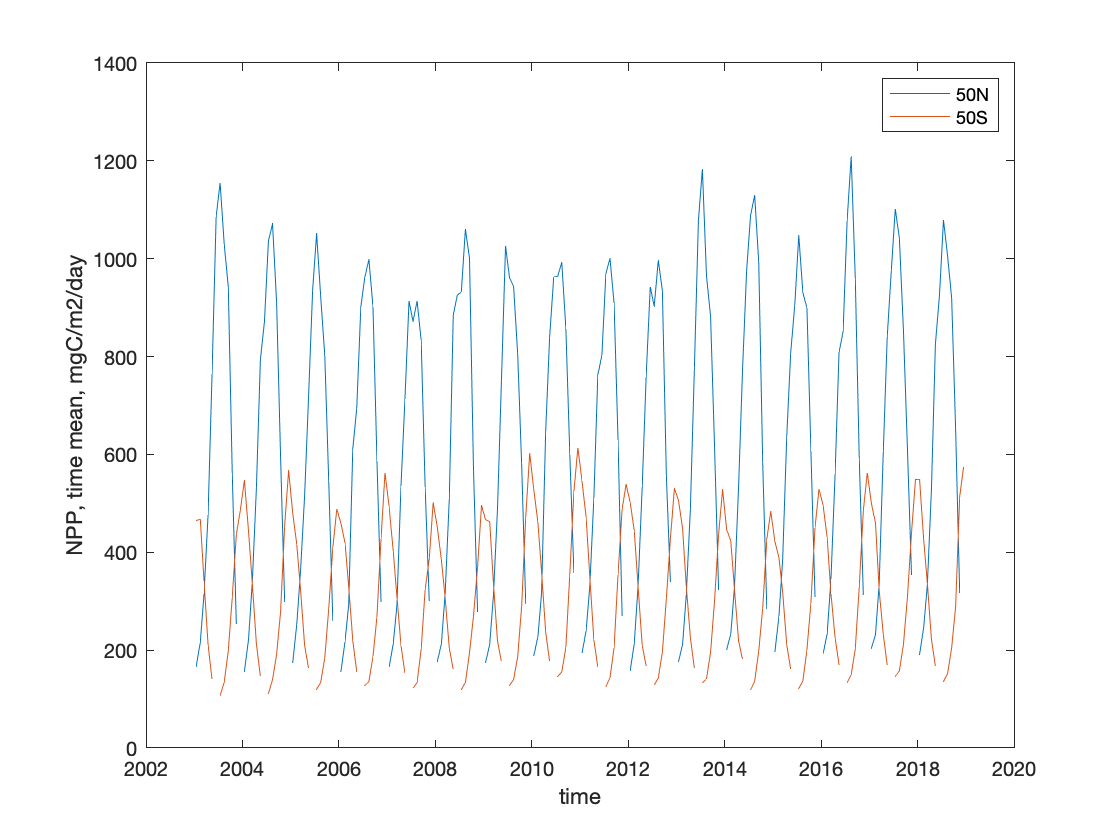

NPPxave = nanmean(NPP,1);
[d,j50n]=min(abs(lat-50)); % find 50N
[d,j50s]=min(abs(lat+50)); % find 50S
dyear=time/365.25+2003;

figure(1);
plot(dyear,squeeze(NPPxave(1,j50n,:)));
hold on;
plot(dyear,squeeze(NPPxave(1,j50s,:)));
legend({'50N' '50S'})
xlabel('time')
ylabel('NPP, time mean, mgC/m2/day')
hold off;

(2) Extract a NPP time series in the eastern tropical Pacific (e.g. 90°W at equator) and plot a time series. Examine the NPP in the 2015-16 El-Nino event

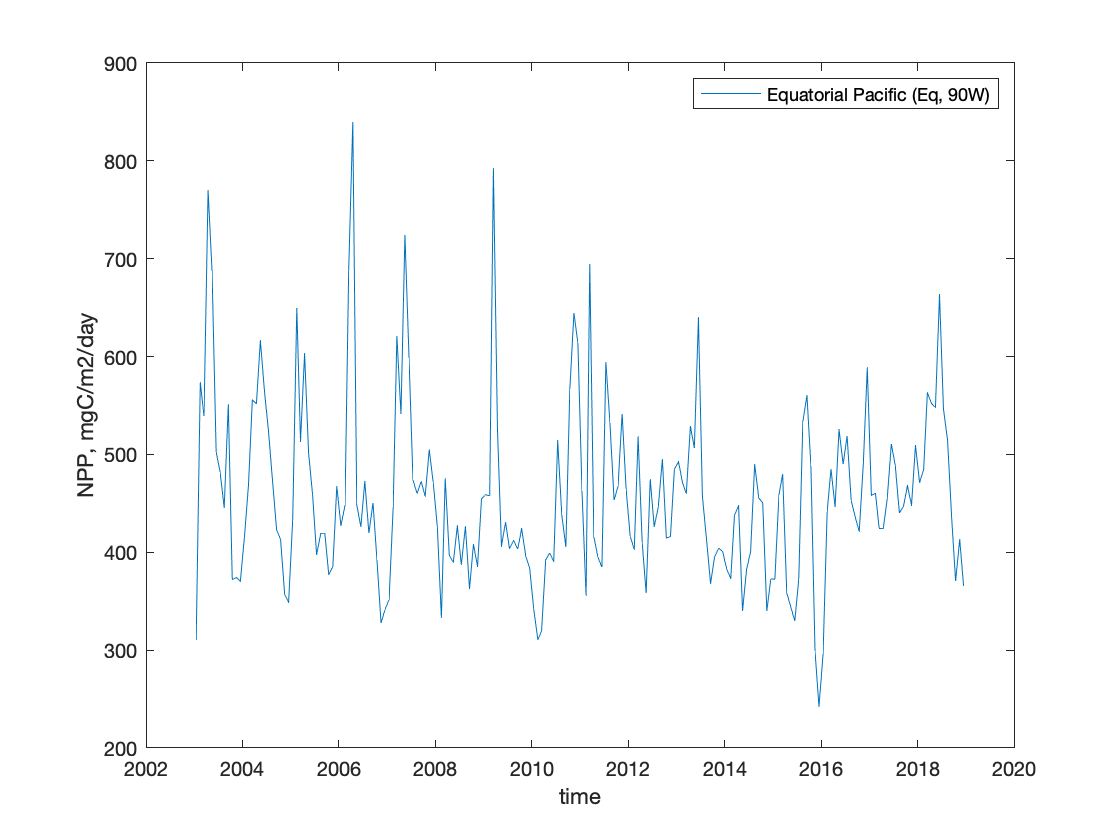

figure(2);
% tropical Pacific
[dummy,Iy]=min(abs(lat));
[dummy,Ix]=min(abs(lon+90));
NPP_EQP=squeeze(NPP(Ix+1,Iy+1,:));
plot(dyear,NPP_EQP);
legend({'Equatorial Pacific (Eq, 90W)'});
xlabel('time')
ylabel('NPP, mgC/m2/day')

(3) We would like to evaluate how different NPP was during 2015/16 event. Calculate the departure of NPP from its climatological means for the December of 2015 and generate a global map. 

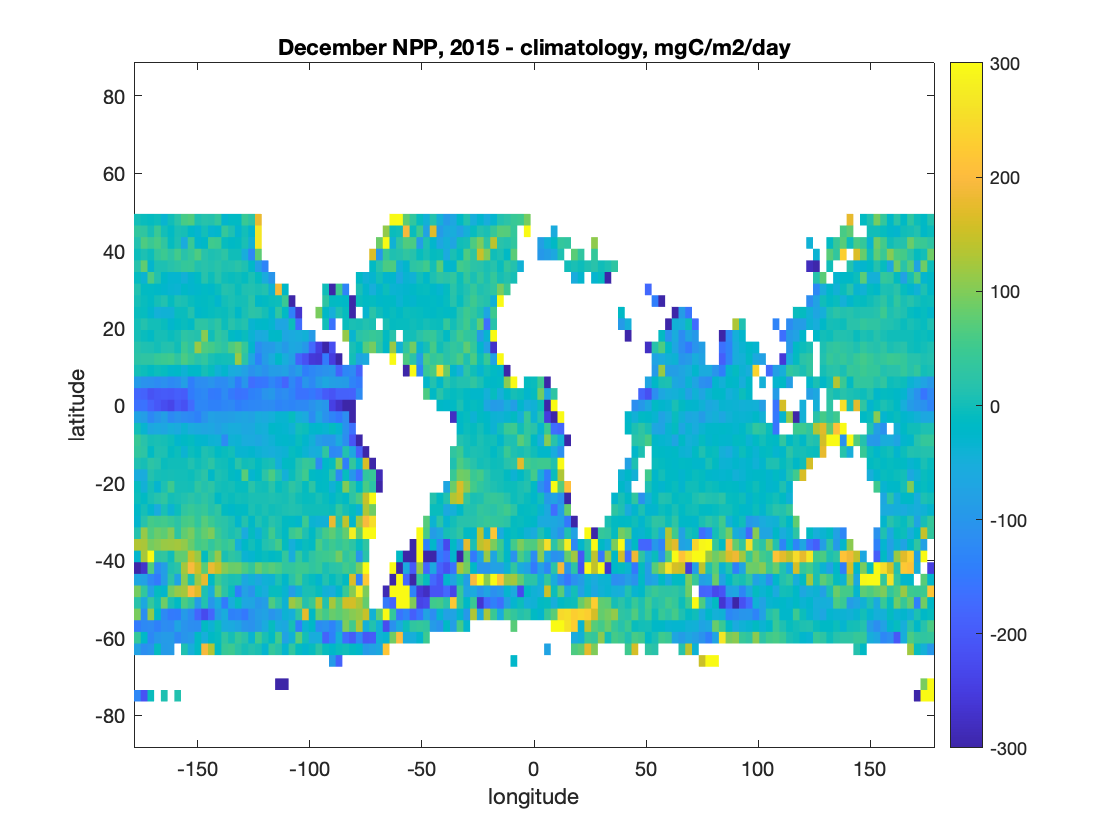

[Y,M,D]=datevec(time);
% select December 2015
dec15 = (M==12) & (Y==2015-2003);
NPP_dec15=squeeze(NPP(:,:,dec15));
% select December all year
dec = (M==12);
NPP_dec=nanmean(NPP(:,:,dec),3);
del = NPP_dec15-NPP_dec;

figure(4);
pcolor(lon,lat,del');
shading flat;
caxis([-300,300])
colorbar;
xlabel('longitude')
ylabel('latitude')
title('December NPP, 2015 - climatology, mgC/m2/day')